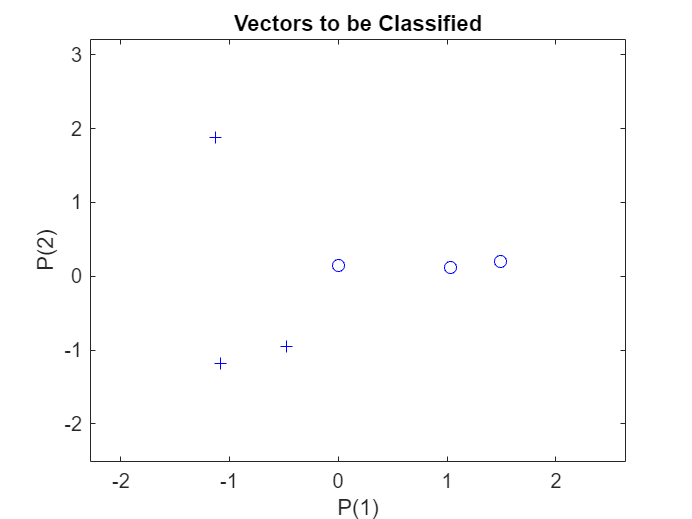

%基于方差极大正交旋转因子得分的福冈判别
clear                                       %清理内存
P=[-1.0814 -0.4748 0.0010 1.4951 1.0309	-1.1319
-1.1878 -0.9568 0.1447 0.2059 0.1168 1.8851];
                                            %输入信号
T=[1 1 0 0 0 1];                            %目标输出（已知类别）
Q=[0.1610 -0.2077]';                        %待判样品——福冈的因子得分
plotpv(P,T);                                %画出两类城市的散点图

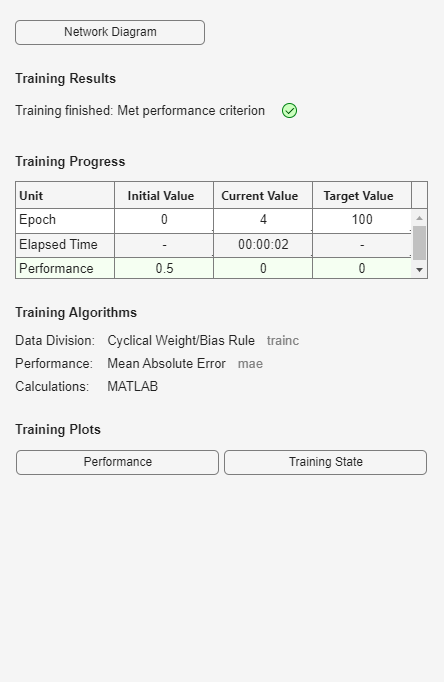

net=newp(minmax(P),1);                      %创建一个感知器网络
net.trainParam.epochs=100;                  %指定最大训练次数
net=train(net,P,T);                         %训练网络

Y=sim(net,Q)                                %输出仿真结果

Y = 0

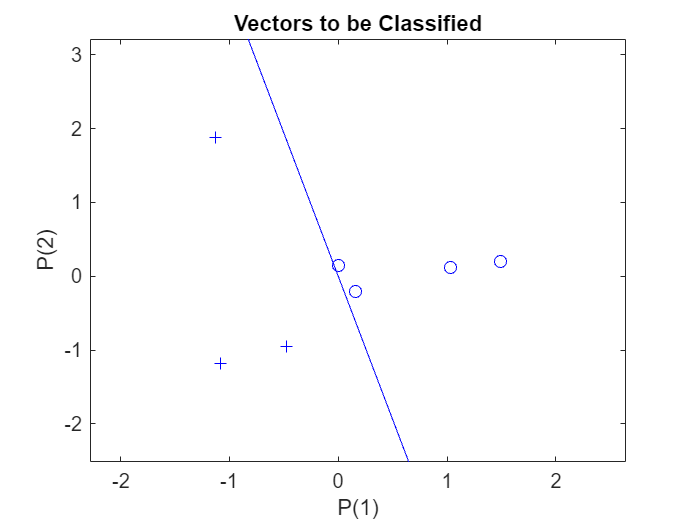

figure;                                     %保持仿真过程图
plotpv([P Q],[T Y]);                        %画出七城市二类别散点图
handle=plotpc(net.iw{1,1},net.b{1});        %添加类别分界线